# Tipos de datos: Valores lógicos

MATLAB representa *datos booleanos* utilizando un tipo de dato llamado **lógico**. Este tipo de dato representa **estados verdaderos** **y falsos** utilizando los números **1 y 0**, respectivamente. Ciertas funciones y operadores de MATLAB devuelven valores lógicos para indicar el cumplimiento de una condición. Puede usar esos valores lógicos para indexar una matriz o ejecutar código condicional.

## Valores lógicos o booleanos

Básicamente existen dos tipos de datos lógicos: **verdadero** y **falso**. Aunque dentro de MATLAB se los representa con `1` y `0` lógicos, respectivamente.

Para crear directamente datos lógicos se pueden utilizar las funciones `true` y `false`.

true

ans = logical
   1


false

ans = logical
   0


Observemos que la salida de cada función es un número, pero hay un texto en cursiva que indica el tipo de dato, en este caso `logical` que hace referencia a un dato de tipo lógico.

### Generar datos lógicos a partir de una operación relacional

Recordemos que existen varias operaciones relacionales. A continuación se muestran estas operaciones y su representación dentro de MATLAB.

**Figura 1.** Operaciones relacionales en MATLAB.

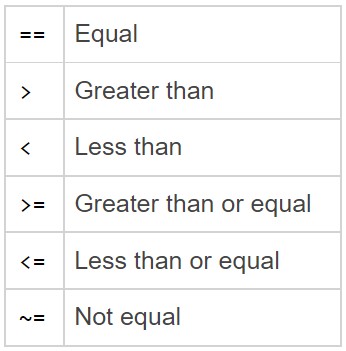

*Tomado de la documentación oficial de MATLAB.*

**El resultado a cada una de estas operaciones siempre será un valor lógico**, o también conocido como un *valor booleano*: **verdadero** o **falso**.

a=1;
b=2;
a>b

ans = logical
   0


a==b

ans = logical
   0


a~=b %esta en el 4 de la parte de arriba del teclado 

ans = logical
   1


#### Observación

No se debe confundir el operador de comparación `==` con el operador de asignación `=`.

- El operador de comparación realiza una *comparación entre valores* y devuelve un *valor lógico*.

- El operador de asignación realiza una *asignación*, o dicho de otro modo, *crea una variable*.

### Función `logical`

La función `logical` permite crear un valor lógico a partir de una entrada. Si la entrada es 0, entonces el valor lógico creado será `0` (o falso), caso contrario, el valor lógico creado será `1` (o verdadero).

c=[1 0 -8 5 8 9 0]

c =      1     0    -8     5     8     9     0


logical(c)

ans = 1×7 logical array
   1   0   1   1   1   1   0


## Operaciones lógicas

En ocasiones será de gran utilidad establecer más de una operación relacional, y cuando ocurra esto se deberá recurrir a las operaciones lógicas.

**Figura 2.** Operaciones lógicas en MATLAB.

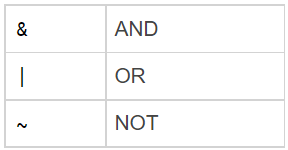

*Tomado de la documentación oficial de MATLAB.*

### Ejemplo

Arturo quiere ir de campamento, pero sus padres le dicen que tendrá permiso si lava los platos y poda el jardín, o si barre la casa y saca a pasear al perro. ¿Qué hará Arturo?

### Solución

Ingrese su solución aquí :)

%caso 1 

p=true;
q=false;
%caso 2

r= true;
s=false;

%condicion
cond=(p & q) | (r & s)

cond = logical
   0


p=true;
q=true;

cond2=(p & q) | (r & s)

cond2 = logical
   1


### Funciones asociadas a arreglos lógicos

Ahora que ya tenemos el concepto de arreglo lógico podemos estudiar algunas funciones que nos serán de utilidad.

#### Función `all`

La función `all` es la conjunción dentro de una matriz. Es decir, si todos los elementos son `true` (o `1` lógico) entonces la salida es `1` lógico, caso contrario la salida es `0` lógico, es decir, `false`.

v=[true true false true true];
all(v)

ans = logical
   0


g=[true true true true];
all(g)

ans = logical
   1


Pero si se aplica esta función sobre un arreglo lógico, entonces realizará la conjunción por la dimensión predominante.

M=[true false; true true]

M = 2×2 logical array
   1   0
   1   1


all(M)

ans = 1×2 logical array
   1   0


all(M,2)

ans = 2×1 logical array
   0
   1


No obstante, también se puede ingresar la dimensión secundaria para que se realice la conjunción por filas.

all(M,2)

ans = 2×1 logical array
   0
   1


#### Función `any`

La función `any` es la disyunción dentro de una matriz. Es decir, si alguno de los elementos es `true` (o `1` lógico) entonces la salida es `1` lógico, caso contrario la salida es `0` lógico, es decir, `false`.

v=[5 8 2 3 9]

v =      5     8     2     3     9


all(v>5)

ans = logical
   0


any(v>5)

ans = logical
   1


Pero si se aplica esta función sobre un arreglo lógico, entonces realizará la disyunción por la dimensión predominante.

M=[true true false; true false false; false false false]

M = 3×3 logical array
   1   1   0
   1   0   0
   0   0   0


any(M)

ans = 1×3 logical array
   1   1   0


No obstante, también se puede ingresar la dimensión secundaria para que se realice la disyunción por filas.

any(M,2)

ans = 3×1 logical array
   1
   1
   0


#### Función nnz

La función `nnz` (**n**umber of **n**on**z**ero elements) permite contar el número de elementos que no son cero de una matriz.

M=[2 1 5 4 8; 5 1 4 8 9; 2 5 4 8 6; 5 4 4 6 6; 5 4 7 4 2]

M =      2     1     5     4     8
     5     1     4     8     9
     2     5     4     8     6
     5     4     4     6     6
     5     4     7     4     2


nnz(M>=7)

ans = 5

**Observación:** Una vez realizado todo este tema, si es necesario, es posible retomar la indexación lógica en el tema que trataba sobre las matrices.

## Material adicional

- [Operaciones relacionales](https://www.mathworks.com/help/matlab/relational-operators.html)

- [Operaciones lógicas (o booleanas)](https://www.mathworks.com/help/matlab/logical-operations.html)